clear;
close all;
clc;

% Load the dataset
load("JNJ_FINAL.mat");

% Extract Prices and Timestamps from the timetable
timestamps = JNJ_FINAL.TimeStamps;
Prices = JNJ_FINAL.Prices;

% Filter: keep only rows from 2013-01-01 to 2020-01-01
idx = (timestamps >= datetime(2013,1,1)) & (timestamps <= datetime(2020,1,1));
timestamps_filtered = timestamps(idx);
z = Prices(idx);

## **Preliminary analysis **

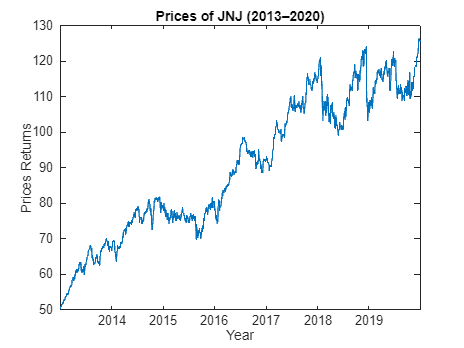

%%  Plot the time series
figure;
plot(timestamps_filtered, z);
title("Prices of JNJ (2013–2020)");
xlabel("Year");
ylabel("Prices Returns");

% parameters
numLagsLBQ = 15; % number of lags for the LBQ test
numLagsARCH = 15; % number of lags for the Engel test
alphaLBQ = 0.05; % significance level of the LBQ test
alphaARCH = 0.05; % significance level of the Engel test
alphaLR = 0.01; % significance level of the likelihood ratio test

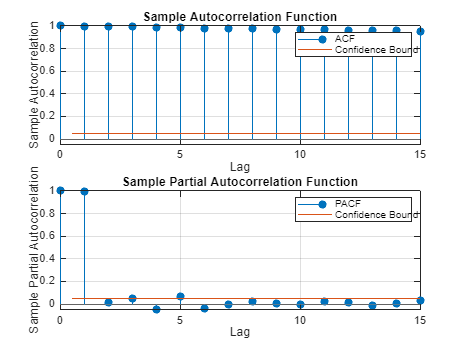

figure
subplot(2,1,1)
autocorr(z,'NumLags',numLagsLBQ);   % plot autocorr
subplot(2,1,2)
parcorr(z,'NumLags',numLagsLBQ); 

% Dickey Fuller Test of the raw series 
[h0_raw,pValue_raw]=adftest(z);  %Dickey fuller test of prices - se h0=0 allora accetto ipotesi nulla quindi la serie ha radice unitaria presente - non stazionaria
% Display the result in the command window
if h0_raw == 0
    fprintf('ADF Test: Failed to reject the null hypothesis (p = %.4f). The series may be non-stationary.\n', pValue_raw);
else
    fprintf('ADF Test: Rejected the null hypothesis (p = %.4f). The series is likely stationary.\n', pValue_raw);
end

ADF Test: Failed to reject the null hypothesis (p = 0.9737). The series may be non-stationary.



% Jarque-Bera test 

if exist('jbtest', 'file')  % Econometrics Toolbox check
    [hJB, pJB] = jbtest(z, 0.05);
    if hJB == 1
        fprintf('Jarque-Bera test: Reject normality (p = %.4f)\n', pJB);
    else
        fprintf('Jarque-Bera test: Fail to reject normality (p = %.4f)\n', pJB);
    end
else
% Custom Jarque-Bera test implementation
    fprintf('Econometrics Toolbox jbtest() not found. Using custom JB test.\n');
    n = length(z);
    s = skewness(z);
    k = kurtosis(z);
    JBstat = (n/6) * (s^2 + (1/4)*(k - 3)^2);
    pJB = 1 - chi2cdf(JBstat, 2);
    alphaJB = 0.05;
    hJB = (pJB < alphaJB);
    if hJB == 1
        fprintf('Jarque-Bera test: Reject normality (p = %.4f)\n', pJB);
    else
        fprintf('Jarque-Bera test: Fail to reject normality (p = %.4f)\n', pJB);
    end
end

Jarque-Bera test: Reject normality (p = 0.0010)


%%  Compute statistics for time series
mean_val_z = mean(z);
median_val_z = median(z);
min_val_z = min(z);
max_val_z = max(z);
std_val_z = std(z);
skewness_val_z = skewness(z);
kurtosis_val_z = kurtosis(z);

% Display results in the command window
fprintf('STATISTICS OF THE TIME SERIES:\n');

STATISTICS OF THE TIME SERIES:


fprintf('Mean: %.4f\n', mean_val_z);

Mean: 90.2796


fprintf('Median: %.4f\n', median_val_z);

Median: 90.2398


fprintf('Min: %.2f\n', min_val_z);

Min: 50.29


fprintf('Max: %.2f\n', max_val_z);

Max: 126.46


fprintf('Standard deviation: %.3f\n', std_val_z);

Standard deviation: 19.493


fprintf('Skewness: %.5f\n', skewness_val_z);

Skewness: -0.02272


fprintf('Kurtosis: %.4f\n', kurtosis_val_z);

Kurtosis: 1.7380


## **LOG RETURNS **

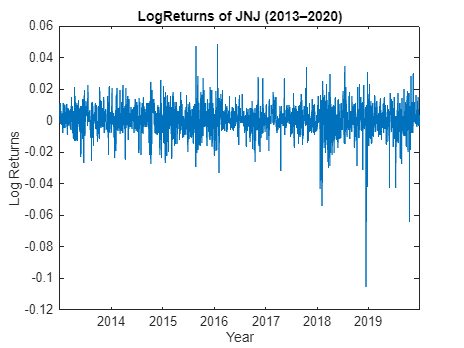


% Extract Prices and Timestamps from the timetable
timestamps = JNJ_FINAL.TimeStamps;
LogPrices = JNJ_FINAL.LogReturns;

% Filter: keep only rows from 2013-01-01 to 2020-01-01
idx = (timestamps >= datetime(2013,1,1)) & (timestamps <= datetime(2020,1,1));
timestamps_filtered = timestamps(idx);
y = LogPrices(idx);
%%  Plot the time series
figure;
plot(timestamps_filtered, y);
title("LogReturns of JNJ (2013–2020)");
xlabel("Year");
ylabel("Log Returns");

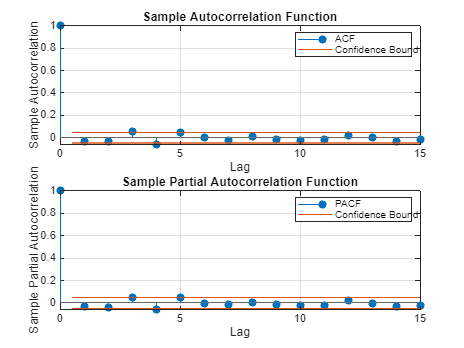

figure
subplot(2,1,1)
autocorr(y,'NumLags',numLagsLBQ);   % plot autocorr
subplot(2,1,2)
parcorr(y,'NumLags',numLagsLBQ); 

% Dickey Fuller Test of the raw series 
[h0_raw,pValue_raw]=adftest(y);  %Dickey fuller test of prices - se h0=0 allora accetto ipotesi nulla quindi la serie ha radice unitaria presente - non stazionaria
% Display the result in the command window
if h0_raw == 0
    fprintf('ADF Test: Failed to reject the null hypothesis (p = %.4f). The series may be non-stationary.\n', pValue_raw);
else
    fprintf('ADF Test: Rejected the null hypothesis (p = %.4f). The series is likely stationary.\n', pValue_raw);
end

ADF Test: Rejected the null hypothesis (p = 0.0010). The series is likely stationary.



% Jarque-Bera test on diff_returns

if exist('jbtest', 'file')  % Econometrics Toolbox check
    [hJB, pJB] = jbtest(y, 0.05);
    if hJB == 1
        fprintf('Jarque-Bera test: Reject normality (p = %.4f)\n', pJB);
    else
        fprintf('Jarque-Bera test: Fail to reject normality (p = %.4f)\n', pJB);
    end
else
% Custom Jarque-Bera test implementation
    fprintf('Econometrics Toolbox jbtest() not found. Using custom JB test.\n');
    n = length(y);
    s = skewness(y);
    k = kurtosis(y);
    JBstat = (n/6) * (s^2 + (1/4)*(k - 3)^2);
    pJB = 1 - chi2cdf(JBstat, 2);
    alphaJB = 0.05;
    hJB = (pJB < alphaJB);
    if hJB == 1
        fprintf('Jarque-Bera test: Reject normality (p = %.4f)\n', pJB);
    else
        fprintf('Jarque-Bera test: Fail to reject normality (p = %.4f)\n', pJB);
    end
end

Jarque-Bera test: Reject normality (p = 0.0010)


%%  Compute statistics for time series
mean_val_y = mean(y);
median_val_y = median(y);
min_val_y = min(y);
max_val_y = max(y);
std_val_y = std(y);
skewness_val_y = skewness(y);
kurtosis_val_y = kurtosis(y);

% Display results in the command window
fprintf('STATISTICS OF THE TIME SERIES:\n');

STATISTICS OF THE TIME SERIES:


fprintf('Mean: %.4f\n', mean_val_y);

Mean: 0.0005


fprintf('Median: %.4f\n', median_val_y);

Median: 0.0006


fprintf('Min: %.2f\n', min_val_y);

Min: -0.11


fprintf('Max: %.2f\n', max_val_y);

Max: 0.05


fprintf('Standard deviation: %.3f\n', std_val_y);

Standard deviation: 0.010


fprintf('Skewness: %.5f\n', skewness_val_y);

Skewness: -1.16195


fprintf('Kurtosis: %.4f\n', kurtosis_val_y);

Kurtosis: 13.6787


## MODEL ESTIMATION

%% ARMA 00 
model_ARMA00 = arima(0,0,0);
%model_ARMA00.Constant = 0; % we set to 0 the constant of the model
[model_ARMA00,~,logL_ARMA00] = estimate(model_ARMA00,y);

 
    ARIMA(0,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue 
                __________    _____________    __________    ________

    Constant    0.00052631     0.00024857        2.1173      0.034231
    Variance    9.7219e-05     1.3717e-06        70.877             0



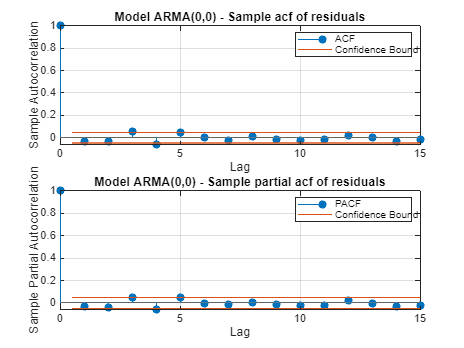


% Analysis of the residuals
e_ARMA00 = infer(model_ARMA00,y);
figure,
subplot(2,1,1)
autocorr(e_ARMA00,'NumLags',numLagsLBQ)
title('Model ARMA(0,0) - Sample acf of residuals')
subplot(2,1,2)
parcorr(e_ARMA00,'NumLags',numLagsLBQ);
title('Model ARMA(0,0) - Sample partial acf of residuals')


lbqdisp(e_ARMA00,numLagsLBQ,alphaLBQ,'residuals');

     Ljung-Box Test (H0: the residuals are uncorrelated)
       --> Hypothesis H0 rejected with p-value = 0.038715 and alpha = 0.05


archdisp(e_ARMA00,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 8.9541e-06 and alpha = 0.05



%ARMA 01
model_ARMA01 = arima(0,0,1);
model_ARMA00.Constant = 0; % we set to 0 the constant of the model
[model_ARMA01,~,logL_ARMA01] = estimate(model_ARMA01,y);

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue 
                __________    _____________    __________    ________

    Constant    0.00052631     0.00024339        2.1624      0.030586
    MA{1}        -0.034678       0.017015       -2.0381      0.041539
    Variance    9.7048e-05     1.3768e-06        70.486             0



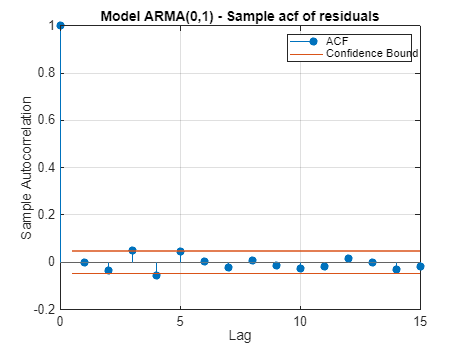


%Analysis of the residuals
e_ARMA01 = infer(model_ARMA01,y);
figure,
autocorr(e_ARMA01,'NumLags',numLagsLBQ)
title('Model ARMA(0,1) - Sample acf of residuals')


lbqdisp(e_ARMA01,numLagsLBQ,alphaLBQ,'residuals');

     Ljung-Box Test (H0: the residuals are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.10361 and alpha = 0.05


archdisp(e_ARMA01,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 3.7713e-06 and alpha = 0.05




% ARMA (1,0)
model_ARMA10 = arima(1,0,0);
model_ARMA00.Constant = 0; % we set to 0 the constant of the model
[model_ARMA10,~,logL_ARMA10] = estimate(model_ARMA10,y);

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue 
                __________    _____________    __________    ________

    Constant    0.00054792     0.00025067        2.1858       0.02883
    AR{1}        -0.034695       0.017019       -2.0386      0.041485
    Variance    9.7024e-05     1.3747e-06        70.579             0



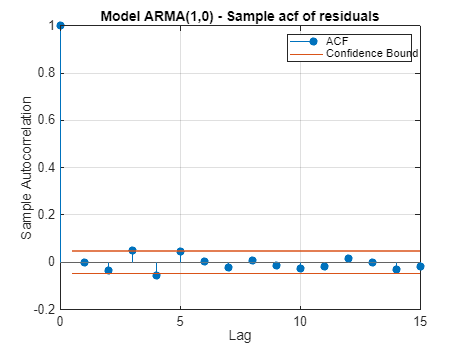



%Analysis of the residuals
e_ARMA10 = infer(model_ARMA10,y);
figure,
autocorr(e_ARMA10,'NumLags',numLagsLBQ)
title('Model ARMA(1,0) - Sample acf of residuals')


lbqdisp(e_ARMA10,numLagsLBQ,alphaLBQ,'residuals');

     Ljung-Box Test (H0: the residuals are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.1004 and alpha = 0.05


archdisp(e_ARMA10,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 3.7961e-06 and alpha = 0.05



% ARMA(1,1)
model_ARMA11 = arima(1,0,1);
[model_ARMA11,~,logL_ARMA11] = estimate(model_ARMA11,y);

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00052631     0.00042346          1.2429    0.21392
    AR{1}            2e-12        0.62699      3.1898e-12          1
    MA{1}        -0.034678        0.62654       -0.055348    0.95586
    Variance    9.7048e-05     1.4058e-06          69.032          0



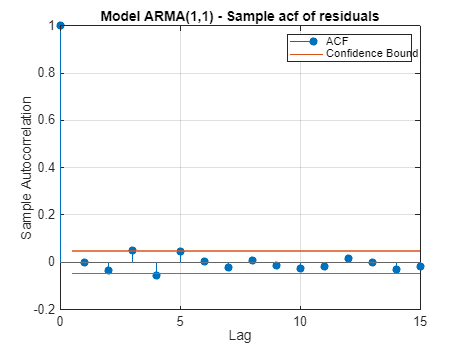


%Analysis of the residuals
e_ARMA11 = infer(model_ARMA11,y);
figure,
autocorr(e_ARMA11,'NumLags',numLagsLBQ)
title('Model ARMA(1,1) - Sample acf of residuals')


lbqdisp(e_ARMA11,numLagsLBQ,alphaLBQ,'residuals');

     Ljung-Box Test (H0: the residuals are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.10361 and alpha = 0.05


archdisp(e_ARMA11,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 3.7713e-06 and alpha = 0.05




% ARMA(2,1)
model_ARMA21 = arima(2,0,1);
[model_ARMA21,~,logL_ARMA21] = estimate(model_ARMA21,y);

 
    ARIMA(2,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00097265     0.00043986        2.2113        0.027018
    AR{1}         -0.78373        0.10659       -7.3525      1.9457e-13
    AR{2}        -0.080727       0.020794       -3.8823      0.00010349
    MA{1}          0.75248        0.10399        7.2363      4.6094e-13
    Variance    9.6287e-05     1.3704e-06        70.262               0



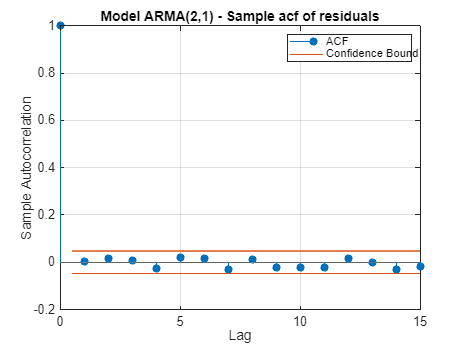


%Analysis of the residuals
e_ARMA21 = infer(model_ARMA21,y);
figure,
autocorr(e_ARMA21,'NumLags',numLagsLBQ)
title('Model ARMA(2,1) - Sample acf of residuals')


lbqdisp(e_ARMA21,numLagsLBQ,alphaLBQ,'residuals');

     Ljung-Box Test (H0: the residuals are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.81287 and alpha = 0.05


archdisp(e_ARMA21,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 6.5751e-06 and alpha = 0.05



% ARMA(1,2)
model_ARMA12 = arima(1,0,2);
[model_ARMA12,~,logL_ARMA12] = estimate(model_ARMA12,y);

 
    ARIMA(1,0,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00052631      0.0003542          1.4859     0.1373
    AR{1}            2e-12        0.46656      4.2867e-12          1
    MA{1}        -0.036003         0.4652       -0.077393    0.93831
    MA{2}        -0.036903       0.029765         -1.2398    0.21504
    Variance    9.6916e-05     1.4059e-06          68.938          0



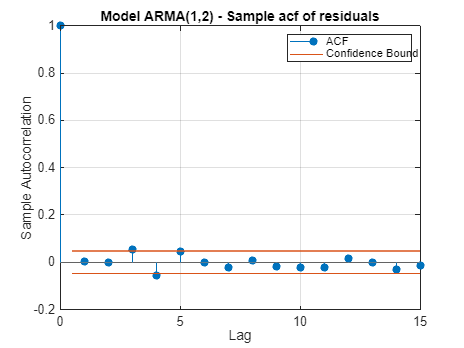


%Analysis of the residuals
e_ARMA12 = infer(model_ARMA12,y);
figure,
autocorr(e_ARMA12,'NumLags',numLagsLBQ)
title('Model ARMA(1,2) - Sample acf of residuals')


lbqdisp(e_ARMA12,numLagsLBQ,alphaLBQ,'residuals');

     Ljung-Box Test (H0: the residuals are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.15731 and alpha = 0.05


archdisp(e_ARMA12,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 2.5514e-06 and alpha = 0.05



% ARMA(2,2)
model_ARMA22 = arima(2,0,2);
[model_ARMA22,~,logL_ARMA22] = estimate(model_ARMA22,y);

 
    ARIMA(2,0,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00052631     0.00035606          1.4781    0.13937
    AR{1}                0        0.74993               0          1
    AR{2}            2e-12        0.57638      3.4699e-12          1
    MA{1}        -0.036003        0.74971       -0.048023     0.9617
    MA{2}        -0.036903        0.59904       -0.061604    0.95088
    Variance    9.6916e-05     1.4107e-06          68.701          0



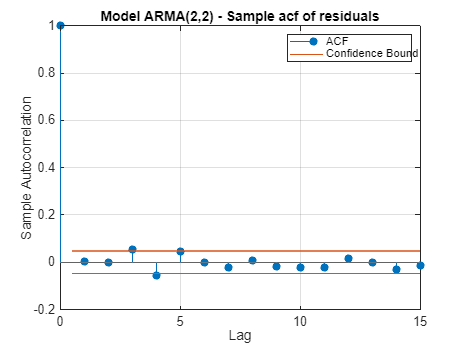


%Analysis of the residuals
e_ARMA22 = infer(model_ARMA22,y);
figure,
autocorr(e_ARMA22,'NumLags',numLagsLBQ)
title('Model ARMA(2,2) - Sample acf of residuals')


lbqdisp(e_ARMA22,numLagsLBQ,alphaLBQ,'residuals');

     Ljung-Box Test (H0: the residuals are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.15731 and alpha = 0.05


archdisp(e_ARMA22,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 2.5514e-06 and alpha = 0.05


%% BEST MODEL:
%%Evaluate all models and select the best
models = {
    'ARMA(0,0)', model_ARMA00, logL_ARMA00;
    'ARMA(0,1)', model_ARMA01, logL_ARMA01;
    'ARMA(1,0)', model_ARMA10, logL_ARMA10;
    'ARMA(1,1)', model_ARMA11, logL_ARMA11;
    'ARMA(2,1)', model_ARMA21, logL_ARMA21;
    'ARMA(1,2)', model_ARMA12, logL_ARMA12;
    'ARMA(2,2)', model_ARMA22, logL_ARMA22;
};

nObs = length(y);

results = cell(size(models,1), 5); % name, logL, numParams, AIC, BIC

for i = 1:size(models,1)
    name = models{i,1};
    mdl = models{i,2};
    logL = models{i,3};

    % Count number of estimated parameters
    numParams = sum(cellfun(@(x) ~isempty(x), {mdl.Constant, mdl.AR{:}, mdl.MA{:}, mdl.Variance}));

    % Compute AIC and BIC
    AIC = -2*logL + 2*numParams;
    BIC = -2*logL + log(nObs)*numParams;

    results{i,1} = name;
    results{i,2} = logL;
    results{i,3} = numParams;
    results{i,4} = AIC;
    results{i,5} = BIC;
end

% Convert to table for display
resultsTable = cell2table(results, ...
    'VariableNames', {'Model', 'LogLikelihood', 'NumParams', 'AIC', 'BIC'});

% Sort by AIC
resultsTable_AIC = sortrows(resultsTable, 'AIC');
disp('Model comparison (sorted by AIC):');

Model comparison (sorted by AIC):


disp(resultsTable_AIC);

        Model        LogLikelihood    NumParams     AIC       BIC  
    _____________    _____________    _________    ______    ______

    {'ARMA(2,1)'}       5647.4            5        -11285    -11257
    {'ARMA(0,1)'}       5640.6            3        -11275    -11259
    {'ARMA(1,0)'}       5640.5            3        -11275    -11259
    {'ARMA(0,0)'}       5639.5            2        -11275    -11264
    {'ARMA(1,2)'}       5641.7            5        -11273    -11246
    {'ARMA(1,1)'}       5640.6            4        -11273    -11251
    {'ARMA(2,2)'}       5641.7            6        -11271    -11239




% Sort by BIC
resultsTable_BIC = sortrows(resultsTable, 'BIC');
disp('Model comparison (sorted by BIC):');

Model comparison (sorted by BIC):


disp(resultsTable_BIC);

        Model        LogLikelihood    NumParams     AIC       BIC  
    _____________    _____________    _________    ______    ______

    {'ARMA(0,0)'}       5639.5            2        -11275    -11264
    {'ARMA(0,1)'}       5640.6            3        -11275    -11259
    {'ARMA(1,0)'}       5640.5            3        -11275    -11259
    {'ARMA(2,1)'}       5647.4            5        -11285    -11257
    {'ARMA(1,1)'}       5640.6            4        -11273    -11251
    {'ARMA(1,2)'}       5641.7            5        -11273    -11246
    {'ARMA(2,2)'}       5641.7            6        -11271    -11239



## **ARCH **

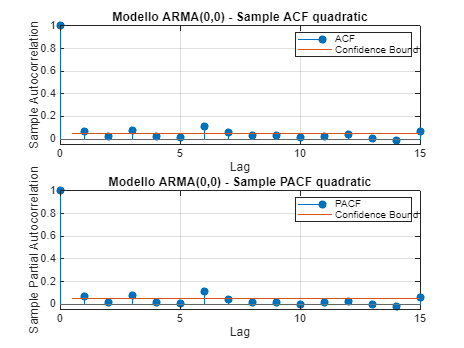

%% Check for the ARCH effects if we needed or not 
figure,
subplot(2,1,1)
autocorr(e_ARMA00.^2, 'NumLags',numLagsARCH)
title('Modello ARMA(0,0) - Sample ACF quadratic')
subplot(2,1,2)
parcorr(e_ARMA00.^2, 'NumLags',numLagsARCH) 
title('Modello ARMA(0,0) - Sample PACF quadratic')


% Engle test
archdisp(e_ARMA00,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 rejected with p-value = 8.9541e-06 and alpha = 0.05



%% GARCH (1,1) 
model_GARCH11 = garch(1,1); %Generate empty GARCH object. IMPORTANT as else wise estimate get's the wrong infos and does the wrong thing!!!
[model_GARCH11,~,logL_GARCH11] = estimate(model_GARCH11,e_ARMA00); %We now ad the estimated residuals. This is done from knowing that the model is GARCH

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    4.668e-06     1.0267e-06        4.5464      5.4562e-06
    GARCH{1}      0.89286      0.0095296        93.693               0
    ARCH{1}      0.061803      0.0064334        9.6066       7.499e-22



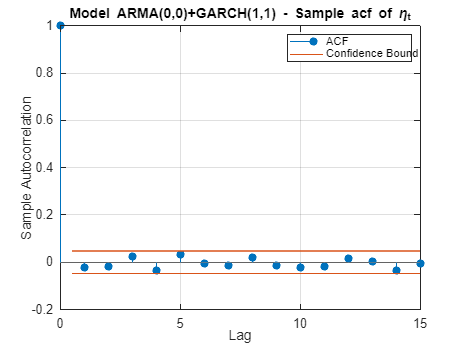


% Analysis of the eta's
h_GARCH11 = infer(model_GARCH11,e_ARMA00);
eta_GARCH11 = e_ARMA00./sqrt(h_GARCH11);

figure,
autocorr(eta_GARCH11,'NumLags',numLagsLBQ)
title('Model ARMA(0,0)+GARCH(1,1) - Sample acf of \eta_t')


% Ljung-Box test
lbqdisp(eta_GARCH11,numLagsLBQ,alphaLBQ,'eta(t)');

     Ljung-Box Test (H0: the eta(t) are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.67348 and alpha = 0.05



% Analysis of the squared eta's
disp('     Plot the sample acf of squared eta(t)...')

     Plot the sample acf of squared eta(t)...


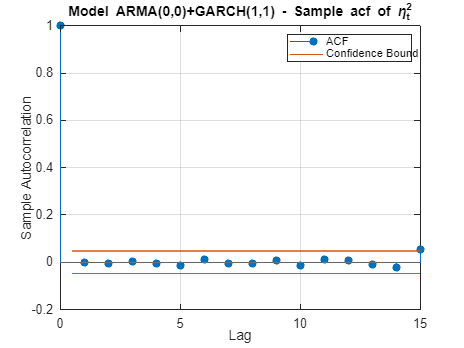

figure,
autocorr(eta_GARCH11.^2,'NumLags',numLagsLBQ)
title('Model ARMA(0,0)+GARCH(1,1) - Sample acf of \eta_t^2')

% Ljung-Box test
lbqdisp(eta_GARCH11.^2,numLagsLBQ,alphaLBQ,'eta(t)^2');

     Ljung-Box Test (H0: the eta(t)^2 are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.93295 and alpha = 0.05


% Engel test
archdisp(eta_GARCH11,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 not rejected with p-value = 0.94337 and alpha = 0.05


%% Overall 
model_ARMA00withGARCH = arima(0,0,0);
model_ARMA00withGARCH.Variance = garch(1,1);
[model_ARMA00withGARCH,~,logL_ARMA00withGARCH] = estimate(model_ARMA00withGARCH,y)

 
    ARIMA(0,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant    0.00063179     0.00022417        2.8183      0.0048275

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    4.741e-06      1.036e-06        4.5762      4.7356e-06
    GARCH{1}      0.89207      0.0096172        92.758               0
    ARCH{1}      0.061704      0.00

model_ARMA00withGARCH =   arima with properties:

     Description: "ARIMA(0,0,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 0
               D: 0
               Q: 0
        Constant: 0.000631793
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: [GARCH(1,1) Model]

logL_ARMA00withGARCH = 5.7010e+03


std_val_y^2

ans = 9.7219e-05

model_ARMA00withGARCH.Variance.GARCH{1}

ans = 0.8921

model_ARMA00withGARCH.Variance.ARCH{1}

ans = 0.0617

model_ARMA00withGARCH.Variance.Constant

ans = 4.7410e-06

model_ARMA00withGARCH.Variance.Constant/(1-model_ARMA00withGARCH.Variance.GARCH{1}-model_ARMA00withGARCH.Variance.ARCH{1}) 

ans = 1.0256e-04

disp(' '), disp('   ESTIMATION OF ARMA(0,0)+GARCH(1,1)')

 
   ESTIMATION OF ARMA(0,0)+GARCH(1,1)


model_ARMA00 = arima(0,0,0); % specify the MA e AR part 
model_ARMA00.Variance = garch(1,1); % and not as a costant! but as a garch
[model_ARMA00,~,logL_ARMA00] = estimate(model_ARMA00,y);

 
    ARIMA(0,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant    0.00063179     0.00022417        2.8183      0.0048275

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    4.741e-06      1.036e-06        4.5762      4.7356e-06
    GARCH{1}      0.89207      0.0096172        92.758               0
    ARCH{1}      0.061704      0.00


% Analysis of the eta's
[e_ARMA00,h_GARCH11] = infer(model_ARMA00,y);
eta_GARCH11 = e_ARMA00./sqrt(h_GARCH11);
disp('     Plot the sample acf of eta(t)...')

     Plot the sample acf of eta(t)...


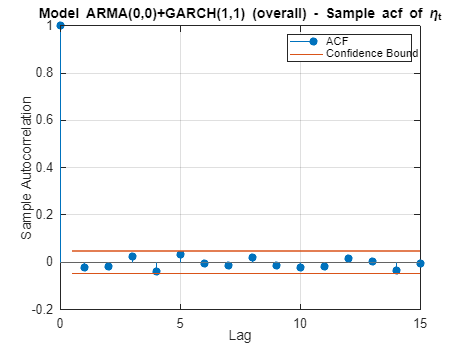

figure,
autocorr(eta_GARCH11,'NumLags',numLagsLBQ)
title('Model ARMA(0,0)+GARCH(1,1) (overall) - Sample acf of \eta_t')

disp('       --> Suggests that the eta(t) are uncorrelated')

       --> Suggests that the eta(t) are uncorrelated



% Ljung-Box test
lbqdisp(eta_GARCH11,numLagsLBQ,alphaLBQ,'eta(t)');

     Ljung-Box Test (H0: the eta(t) are uncorrelated)
       --> Hypothesis H0 not rejected with p-value = 0.67066 and alpha = 0.05



% Analysis of the squared eta's
disp('     Plot the sample acf of squared eta(t)...')

     Plot the sample acf of squared eta(t)...


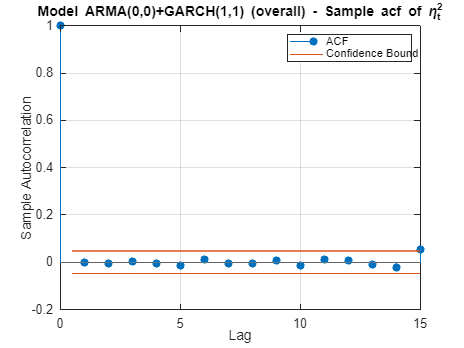

figure,
autocorr(eta_GARCH11.^2,'NumLags',numLagsLBQ)
title('Model ARMA(0,0)+GARCH(1,1) (overall) - Sample acf of \eta_t^2')

disp('       --> Suggests that the squared eta(t) are uncorrelated')

       --> Suggests that the squared eta(t) are uncorrelated




% Engel test
archdisp(eta_GARCH11,numLagsARCH,alphaARCH);

     Engel Test (H0: residuals exhibit no conditional heteroscedasticity)
       --> Hypothesis H0 not rejected with p-value = 0.94176 and alpha = 0.05


**FORECASTING**


mu = 0.00063179;           % Mean return from ARIMA(0,0,0)
omega = 4.741e-06;       % GARCH constant
alpha1 = 0.061704;       % ARCH coefficient
beta1 = 0.89207;         % GARCH coefficient
noiseType = 'Gaussian';  % Innovation distribution
%% Model Definition
modelGARCH = garch('Constant', omega, 'ARCH', alpha1, 'GARCH', beta1, 'Distribution', noiseType);
model_ARMA00 = arima('Constant', mu, 'AR', {}, 'MA', {}, 'Variance', modelGARCH);

SIMULATION

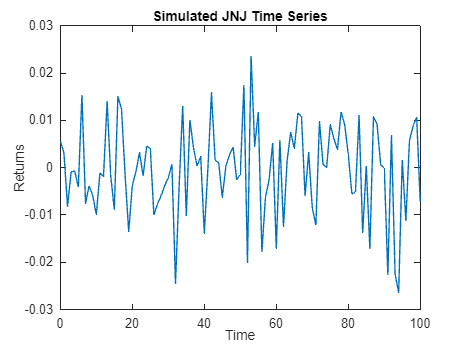

maxLag = 30;     % Forecast horizon
tmax = 100;      % Time series length

[Y, E, H] = simulate(model_ARMA00, tmax+1); 
% No initial condition needed for ARMA(0,0)


%% Sample Mean and Variance
estMean = mean(Y);
estVar = var(Y,1,2);
%% Plot: Time Series
figure,
plot(0:tmax, Y)
title('Simulated JNJ Time Series')
xlabel('Time')
ylabel('Returns')

CONDITIONAL VARIANCE 

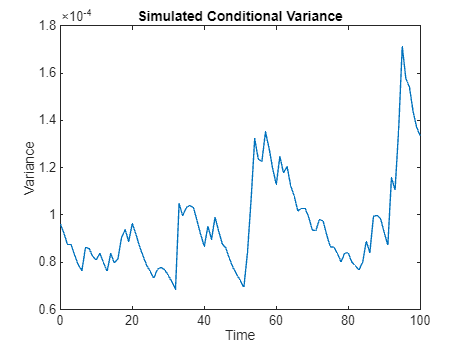


%% Plot: Conditional Variance
figure,
plot(0:tmax, H)
title('Simulated Conditional Variance')
xlabel('Time')
ylabel('Variance')

ACF PACF 

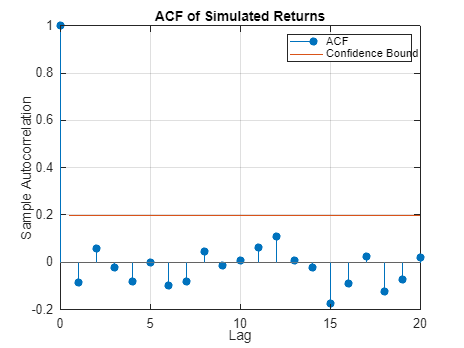

%% Autocorrelation and Partial Autocorrelation
nLags = 20;
figure, autocorr(Y, 'NumLags', nLags)
title('ACF of Simulated Returns')

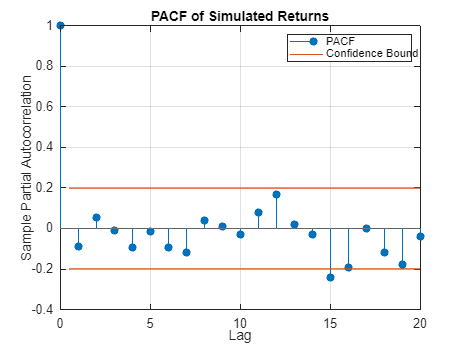


figure, parcorr(Y, 'NumLags', nLags)
title('PACF of Simulated Returns')

FORECAST 

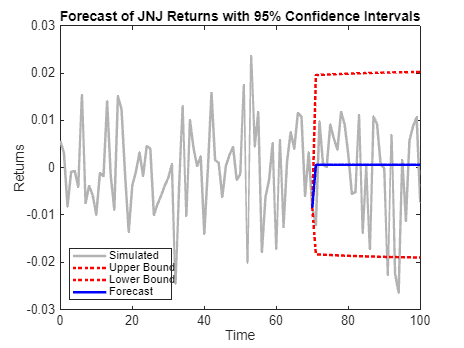

%% Forecast (tmax - maxLag used for training)
[Ypred, YMSE] = forecast(model_ARMA00, maxLag, ...
    'Y0', Y(1:tmax+1-maxLag), ...
    'E0', E(1:tmax+1-maxLag), ...
    'V0', H(1:tmax+1-maxLag));
%% Forecast Confidence Intervals
confLevel = 0.95;
u = norminv((1+confLevel)/2,0,1);
Ysup = Ypred + u * sqrt(YMSE);
Yinf = Ypred - u * sqrt(YMSE);
%% Forecast Plot with Confidence Bands
figure,
plot(0:tmax, Y, 'Color', [0.7 0.7 0.7], 'LineWidth', 2)
hold on
plot(tmax-maxLag:tmax, [Y(tmax+1-maxLag); Ysup], 'r:', 'LineWidth', 2)
plot(tmax-maxLag:tmax, [Y(tmax+1-maxLag); Yinf], 'r:', 'LineWidth', 2)
plot(tmax-maxLag:tmax, [Y(tmax+1-maxLag); Ypred], 'b-', 'LineWidth', 2)
hold off
title('Forecast of JNJ Returns with 95% Confidence Intervals')
xlabel('Time')
ylabel('Returns')
legend('Simulated', 'Upper Bound', 'Lower Bound', 'Forecast', 'Location', 'Best')